**Script to demonstrate a FjordRPM simulation of fjord response to**

varying subglacial discharge input. The shelf conditions are constant in time but vary with depth, using input data from Uummannaq Bay. We use a 80 km long fjord, 6 km wide, with no sill. There are icebergs. The main example here assumes a single glacier with a single plume but the comments also shows how to have multiple glaciers or plumes.

%% clear workspace and close any figures to ensure clean environment
clear; close all;


% put FjordRPM code on path - need to update to the location of your code
path2sourcecode = 'C:\Users\efc4\Documents\MATLAB\fjordrpm\';
addpath(genpath(path2sourcecode));



%% get basic constants and default controlling parameters
p = default_parameters;

% can adjust any of the default parameters afterwards if needed
% p.C0 = 5e4; % for example adjust shelf exchange parameter
% p.run_plume_every = 10; % or update plume model only every 10 time steps


%% set up fjord geometry
p.W = 6e3; % fjord width (m)
p.L = 80e3; % fjord length (m)
p.H = 800; % fjord depth (m)
p.sill = 1; % p.sill=1 for presence of sill, p.sill=0 for no sill
p.Hsill = 400; % sill depth below surface (m), only used if p.sill=1


%% set up glacier geometry
% (only used if there is non-zero subglacial discharge)
p.Hgl = 800; % grounding line depth (m)
p.Wp = 250; % subglacial discharge plume width (m)

% in the case of multiple plumes, either at the same glacier or at
% different glaciers, specify vectors of grounding line depth and plume
% width. for example, 3 glaciers of grounding line depth 800, 700, 600 m
% and plume width 300, 200 and 300 m would require
% p.Hgl = [800,700,600];
% p.Wp = [300,200,300];


%% set up model layers
p.N = 40; % number of layers
a.H0 = (p.H/p.N)*ones(p.N,1); % layer thicknesses, here taken to be equal


%% set up time stepping
dt = 0.2; % time step (in days)
t_end = 3*365; % time to end the simulation (in days)
t = 0:dt:t_end; % resulting time vector for simulation
p.t_save = 0:1:t_end; % times on which to save output


%% set up shelf forcing - here constant in time and depth
% for more complexity see other examples
% f.ts must have dimensions 1 x nt
% f.zs must have dimensions nz x 1
% f.Ss and f.Ts must have dimensions nz x nt

%f.ts = [0,t_end]; % time vector for shelf forcing
%f.zs = [-p.H;0]; % depth vector for shelf forcing (negative below surface)
%f.Ss = 34*ones(length(f.zs),length(f.ts)); % shelf salinity on (zs,ts)
%f.Ts = 3*ones(length(f.zs),length(f.ts)); % shelf temperature on (zs,ts)

% load in ctd data

matPath = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\processed\f_ctd.mat"

matPath = "C:\Users\efc4\OneDrive - University of St Andrews\Desktop\PhD\umq_fjords\data\processed\f_ctd.mat"


% safe load into a struct
S = load(matPath,'f');   % S.f contains your struct
f = S.f;                 % extract the struct

% 1 x 1 or set to profile time
% assume t is the model time vector (row or column)
t = reshape(t,1,[]);                % 1 x nt_model

% if f.Ss is a single column, repeat it to match t
if size(f.Ss,2) == 1 && numel(t) > 1
    f.ts = t;                       % use model times as forcing times
    f.Ss = repmat(f.Ss, 1, numel(t)); 
    f.Ts = repmat(f.Ts, 1, numel(t));
end

f.zs = -f.zs

f = struct with fields:
     zs: [6670×1 double]
     ts: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2 2.2000 2.4000 2.6000 2.8000 3 3.2000 3.4000 3.6000 3.8000 4 4.2000 4.4000 4.6000 4.8000 5 5.2000 5.4000 5.6000 5.8000 6 6.2000 6.4000 6.6000 6.8000 7 7.2000 7.4000 … ] (1×5476 double)
     Ss: [6670×5476 double]
     Ts: [6670×5476 double]
    tsg: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2 2.2000 2.4000 2.6000 2.8000 3 3.2000 3.4000 3.6000 3.8000 4 4.2000 4.4000 4.6000 4.8000 5 5.2000 5.4000 5.6000 5.8000 6 6.2000 6.4000 6.6000 6.8000 7 7.2000 7.4000 … ] (1×5476 double)
    Qsg: [1.4967e-17 1.6358e-17 1.7876e-17 1.9534e-17 2.1343e-17 2.3317e-17 2.5473e-17 2.7824e-17 3.0391e-17 3.3191e-17 3.6245e-17 3.9578e-17 4.3213e-17 4.7177e-17 5.1501e-17 5.6216e-17 6.1357e-17 6.6963e-17 7.3074e-17 7.9735e-17 … ] (1×5476 double)


**Set up subglacial discharge forcing**

% here we use a sin curve to represent seasonally varying subglacial discharge

% f.tsg must have dimensions 1 x nt

% f.Qsg must have dimensions num plumes x nt

f.tsg = t; % time vector for subglacial discharge
f.Qsg = 300*exp(-((mod(t,365)-200)/30).^2)

f = struct with fields:
     zs: [6670×1 double]
     ts: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2 2.2000 2.4000 2.6000 2.8000 3 3.2000 3.4000 3.6000 3.8000 4 4.2000 4.4000 4.6000 4.8000 5 5.2000 5.4000 5.6000 5.8000 6 6.2000 6.4000 6.6000 6.8000 7 7.2000 7.4000 … ] (1×5476 double)
     Ss: [6670×5476 double]
     Ts: [6670×5476 double]
    tsg: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2 2.2000 2.4000 2.6000 2.8000 3 3.2000 3.4000 3.6000 3.8000 4 4.2000 4.4000 4.6000 4.8000 5 5.2000 5.4000 5.6000 5.8000 6 6.2000 6.4000 6.6000 6.8000 7 7.2000 7.4000 … ] (1×5476 double)
    Qsg: [1.4967e-17 1.6358e-17 1.7876e-17 1.9534e-17 2.1343e-17 2.3317e-17 2.5473e-17 2.7824e-17 3.0391e-17 3.3191e-17 3.6245e-17 3.9578e-17 4.3213e-17 4.7177e-17 5.1501e-17 5.6216e-17 6.1357e-17 6.6963e-17 7.3074e-17 7.9735e-17 … ] (1×5476 double)


% in the case of multiple plumes we add more rows to f.Qsg
% for example for three plumes with the same subglacial discharge
% f.Qsg(1,:) = 300*exp(-((mod(t,365)-200)/30).^2);
% f.Qsg(2,:) = 300*exp(-((mod(t,365)-200)/30).^2);
% f.Qsg(3,:) = 300*exp(-((mod(t,365)-200)/30).^2);


%% fjord initial conditions
% set up to be same as initial shelf profiles
[a.T0, a.S0] = bin_shelf_profiles(f.Ts(:,1), f.Ss(:,1), f.zs, a.H0);



% set up icebergs
% need to specify the iceberg-ocean surface area in each layer. assume an 
% exponential profile with total surface area 200 km^2 = 2e8 m^2
zc = cumsum(a.H0)-a.H0/2; % depth of centre of layers
iceprofile = exp(-zc/100); % profile before scaling
a.I0 = (1e8/sum(iceprofile))*iceprofile; % surface area profile used by FjordRPM (m^2)


%% run the model
% p.plot_runtime = 1; % plot while simulation runs - fun but quite slow
s = run_model(p, t, f, a);

Riverine input flux (f.Qr) not specified: setting to 0.
Temperature of riverine input (f.Tr) not specified: setting to 0.
Salinity of riverine input (f.Sr) not specified: setting to 0.
Air temp (f.Ta) not specified: setting air-sea heat flux to 0.


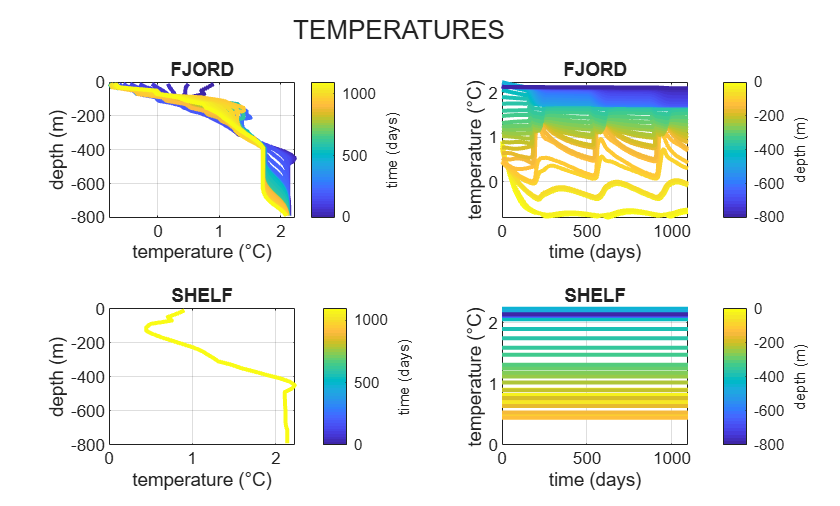

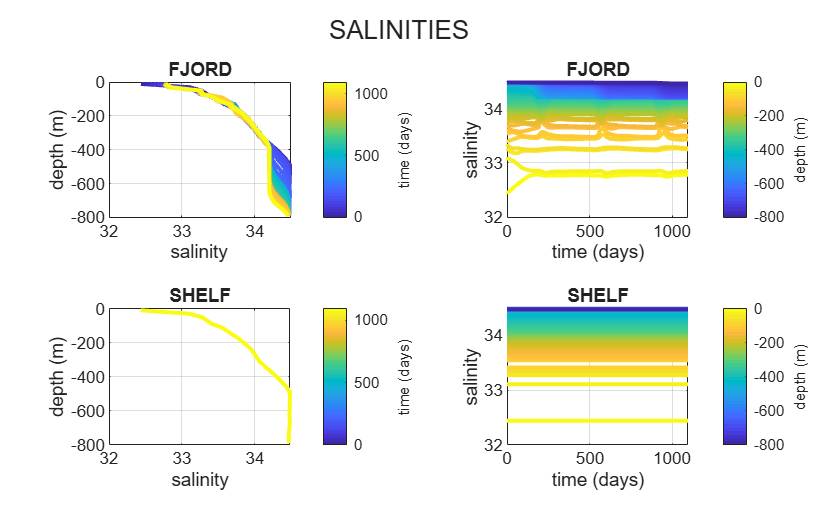

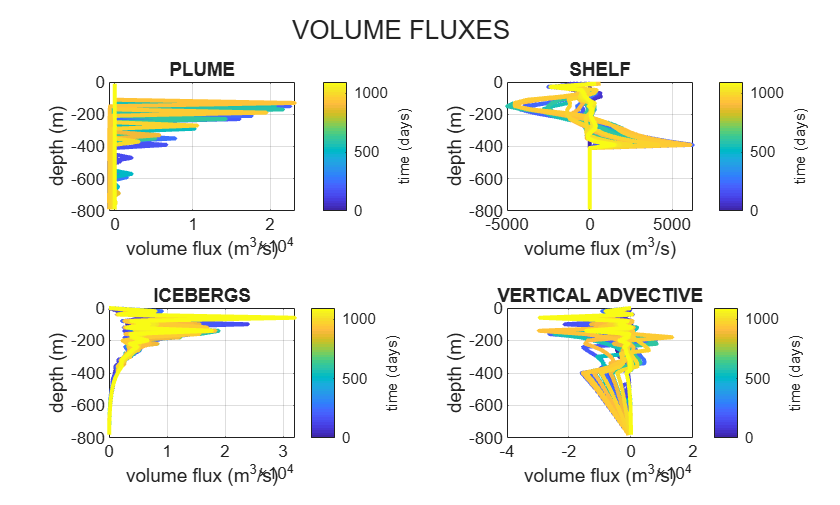

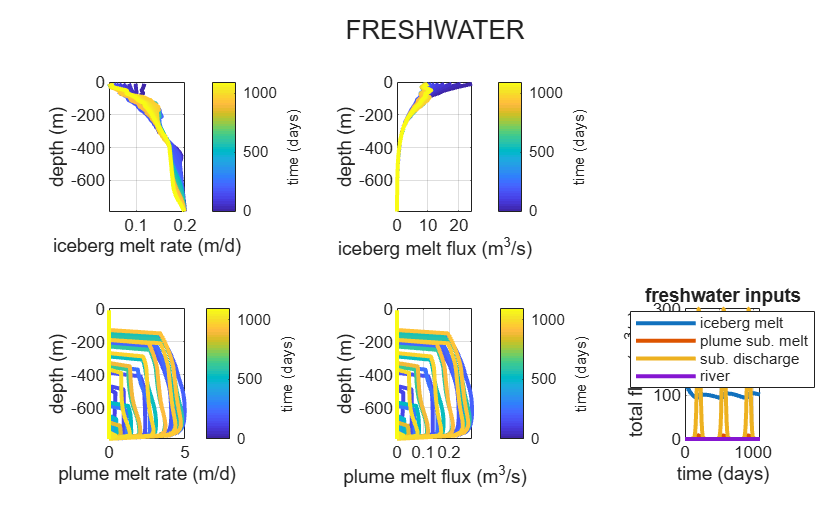


%% save the output
save experiment4_combined.mat s p t f a

%% make an animation of the output (takes a few minutes)
% animate(p,s,50,'example1_subglacial_discharge');

%% make basic plots of the output
plotrpm(p,s,50);